**Classifying Iris Data Set :**

In this case-study, it is required to devise a classifier for classifying Iris flower data-set using  a computational intelligence technique.  The data-set is to be  downloaded from the **UC Irvine Machine Learning Repository. **The classifier is designed and evaluated using a systematic approach to data analytics. The data-set used here is** Iris Data Set, **available for download from: [Data Folder](https://archive.ics.uci.edu/ml/machine-learning-databases/iris/), [Data Set Description](https://archive.ics.uci.edu/ml/machine-learning-databases/iris/iris.names), one can download it in MATLAB as follows:

filename='wdbc.data' 

filename = 'wdbc.data'

url = ['https://archive.ics.uci.edu/ml/machine-learning-databases/breast-cancer-wisconsin/' filename];

file_destination = filename;

%websave(file_destination,url);
T = readtable(file_destination, 'FileType','text', 'Delimiter', 'comma')

T = 569×32 table
       Var1       Var2     Var3     Var4     Var5     Var6      Var7       Var8       Var9       Var10     Var11      Var12     Var13     Var14     Var15    Var16     Var17       Var18       Var19      Var20       Var21      Var22      Var23    Var24    Var25    Var26    Var27     Var28     Var29      Var30     Var31      Var32 
    __________    _____    _____    _____



inIris_data=T(:, 3:32);
inpIris_data=table2array(inIris_data);
outIris_data=zeros(size(inIris_data,1), 2)

outIris_data =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


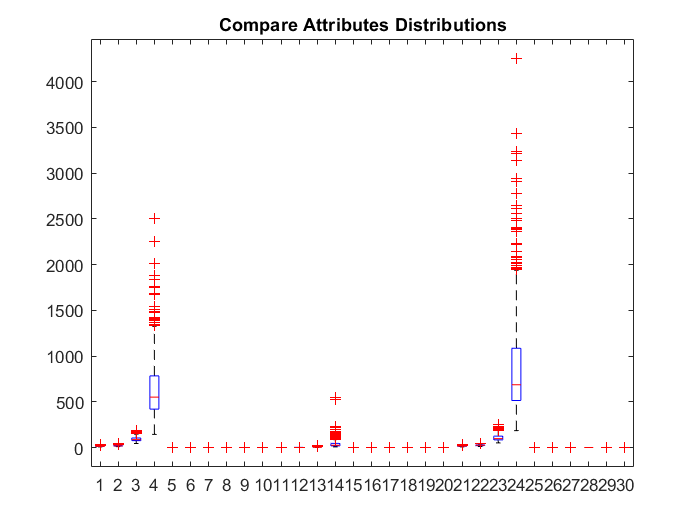

%Graphically inspect the data through box-plots.

boxplot(inpIris_data(:,:))
title('Compare Attributes Distributions')

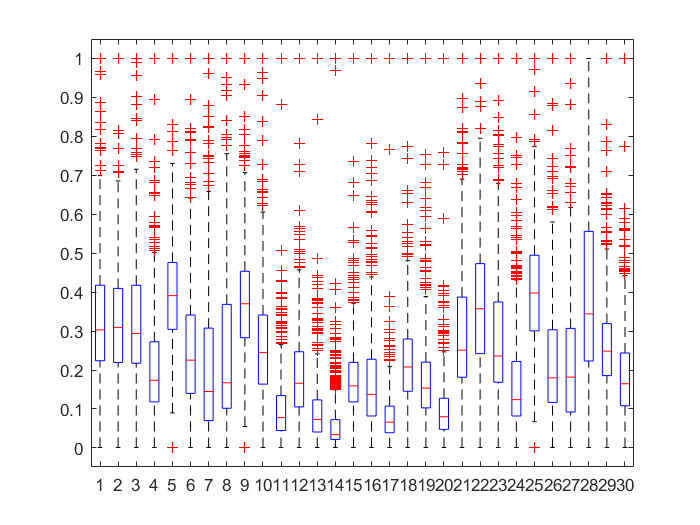



FP.ymin=0.001; FP.ymax=1.00;

[Y,PS] = mapminmax(inpIris_data', FP);

boxplot(Y')

w=6;
figure, boxplot(Y', 'Whisker',w, 'PlotStyle','compact')

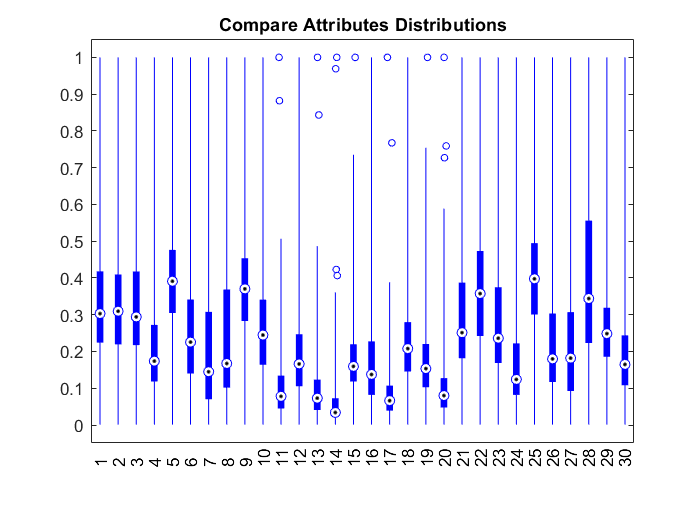

title('Compare Attributes Distributions')

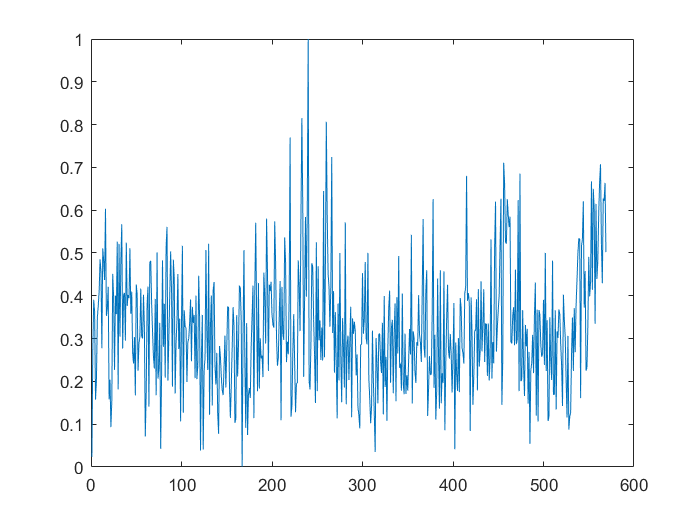


y_data=Y';
plot(y_data(:,2))


q1 = quantile(y_data(:,2),0.25); 

%Find the third quartile (q3).
q3 = quantile(y_data(:,2),0.75);

%Find the the lower whisker.
lowerWhisker=q1 - w * (q3 - q1)

lowerWhisker = -0.9225

%Find the the upper whisker.
upperWhisker=q3 + w * (q3 - q1)

upperWhisker = 1.5513

meanValue=mean(y_data(:,2))

meanValue = 0.3246

outliers = (y_data(:,2)>upperWhisker)|(y_data(:,2)<lowerWhisker)

outliers = 569×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


Noutliers=sum(outliers)

Noutliers = 0

% Let us assign NaN (not a number) to the outlier(s).
y_data(outliers,2)=NaN;

% Let us plot the data with NaN.
plot(y_data(:,2))

%By comparing this plot with the one without replacement, one can clearly see what data instance(s) are replaced with NaN.

% Let us now replace the missing values (set to NaN). 
% Here we fill the missing data using linear interpolation, 
% and return the filled vector F and the logical vector TF. 
% The value 1 (true) in entries of TF corresponds to the values of F that were filled.
[F,TF] = fillmissing(y_data(:,2),'linear',1);

% Let us plot again the attribute after filling the missing value(s).
plot(F)

% Let us set the target labels the output target variable outIris_data.
for i=1:size(inIris_data,1)
    if (strcmp(table2cell(T(i,2)), 'M'))
        outIris_data(i,1)=1;
    else
        outIris_data(i,2)=1;
    end
end

%Assign all the attributes including the ones after outliers corrections as row vectors to the input patterns 'inputs'. 
inputs=[y_data(:,1), F, y_data(:,3:4)]';

%Assign the output target variables as row vectors to the output target patterns 'targets'.
targets=outIris_data';


Let us  now build a multi-layer perceptron (MLP) network. The default network for function fitting  problems, patternnet, is a feedforward network with the default tan-sigmoid transfer function in the hidden layer, and a softmax transfer function in the output layer. The network has two output neurons, because there are two target values (categories) associated with each input vector. Each output neuron represents a category.

When an input vector of the appropriate category is applied to the network, the corresponding neuron should produce a 1, and the other neurons should output a 0. To create and initialise the network, enter the following commands:

%Let us fix the seed for initialising ranmdom number generation, so that
%same values are initialised in the repeated runs.
rng(0)

% Initilise the network.
hiddenLayerSize =1;
net = patternnet(hiddenLayerSize, 'trainlm');

Set up the division of data for training with cross-validation.

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio   = 15/100;
net.divideParam.testRatio  = 15/100;

With these settings, the input vectors and target vectors will be randomly divided, with 70% used for training, 15% for validation and 15% for testing.

Train the network using train command.

[net,tr] = train(net,inputs,targets);

During training, as in function fitting, the training window opens. This window displays training progress. To interrupt training at any point, click Stop Training.

Test the network. After the network has been trained, you can use it to compute the network outputs. The following code calculates the network outputs, errors and overall performance.

outputs = net(inputs);
errors = gsubtract(targets,outputs);
performance = perform(net,targets,outputs)

performance = 0.0553

It is also possible to calculate the network performance only on the test set, by using the testing indices, which are located in the training record. View the network diagram.

view(net)

Plot the training, validation, and test performance.

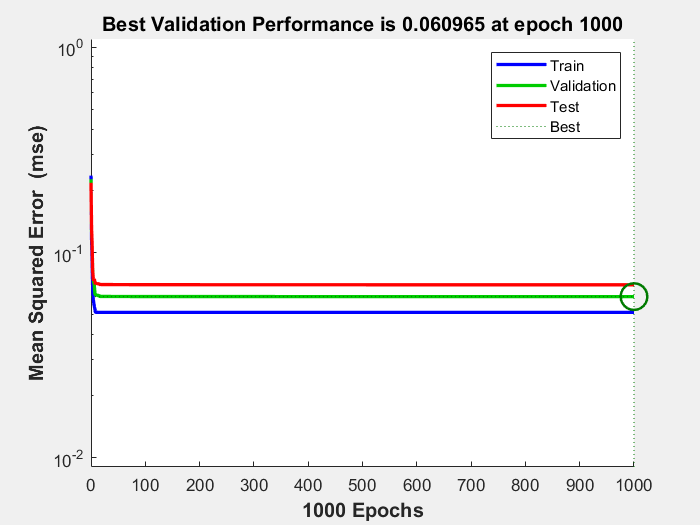

figure, plotperform(tr)

Use the plotconfusion function to plot the confusion matrix. It shows the various types of errors that occurred for the final trained network.

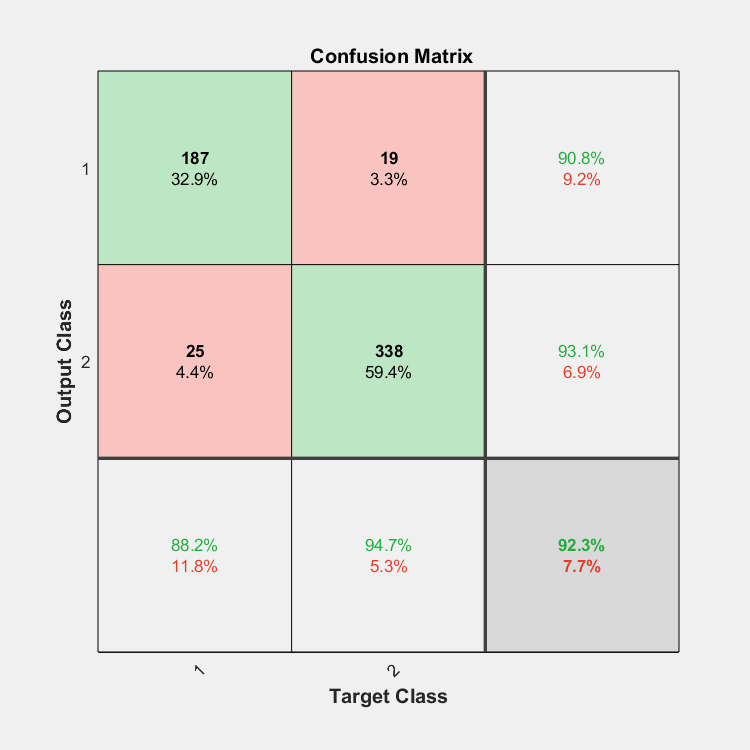

figure, plotconfusion(targets,outputs)

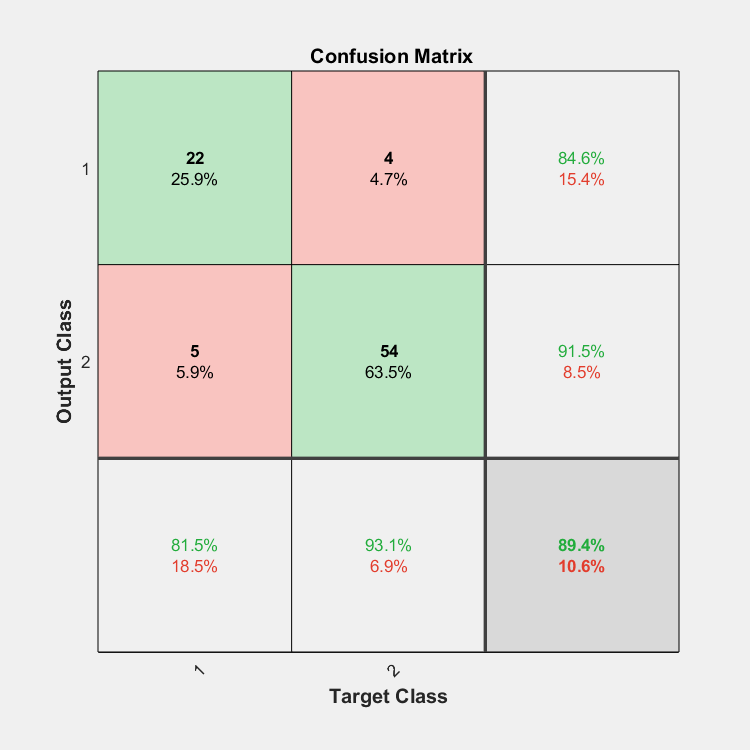

figure, testTargets=targets(:, tr.testInd);
testInputs=inputs(:, tr.testInd);
testOutputs=sim(net, testInputs);
plotconfusion(testTargets,testOutputs)